clc,clear; 

imageFolder = '/home/lzh/hair/seg_pic_label/hair_202407_per15';
labelFile = '/home/lzh/hair/trainedModel_unet_segnet_deeplab/gTruth_20241112.mat';
pixelLabelFolder = '/home/lzh/hair/seg_pic_label/PixelLabelData_1';
% 读取标注文件
gTruth = load(labelFile).gTruth;


% 创建图像数据存储
imds = imageDatastore(imageFolder, 'FileExtensions', '.Tif', 'IncludeSubfolders', true);

% 自定义图像读取函数，使单通道图像变为三通道
imds.ReadFcn = @(x) preprocessImage(x);

% 定义自定义预处理函数
function img = preprocessImage(filename)
    img = imread(filename);
    if size(img, 3) == 1  % 检查是否为单通道图像
        img = repmat(img, [1, 1, 3]);  % 复制单通道到三个通道
    end
    img = imresize(img, [512, 640]);  % 缩放图像到指定大小
end

classNames= ["hair","background","scale_bar","length"];
pxds=pixelLabelDatastore(gTruth);  %标签图像

Analyze Dataset Statistics

tbl = countEachLabel(pxds)

tbl = 4×3 table
         Name         PixelCount    ImagePixelCount
    ______________    __________    _______________

    {'hair'      }    3.5902e+08      2.1443e+09   
    {'background'}    1.6496e+09      2.1443e+09   
    {'scale_bar' }    1.3001e+08       2.143e+09   
    {'length'    }    4.0658e+06      2.1378e+09   


frequency

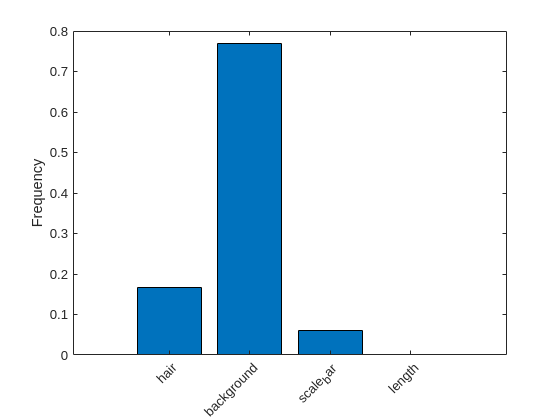

frequency = tbl.PixelCount/sum(tbl.PixelCount);

figure
bar(1:numel(classNames),frequency)
xticks(1:numel(classNames)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

create DeepLab v3+ Based on ResNet18

[imdsTrain, imdsVal, pxdsTrain, pxdsVal] = partitionData(imds, pxds);

% 定义网络架构 - SegNet
imageSize = [512 640 3]; % 输入图像大小
numClasses = numel(pxds.ClassNames);


lgraph = deeplabv3plusLayers(imageSize,numClasses,"resnet18");

disp(class(lgraph));

nnet.cnn.LayerGraph


Balance Classes Using Class Weighting

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq;
pxLayer = pixelClassificationLayer('Name','labels','ClassNames', tbl.Name, 'ClassWeights', classWeights)

pxLayer =   PixelClassificationLayer - 属性:

            Name: 'labels'
         Classes: [hair    background    scale_bar    length]
    ClassWeights: [4×1 double]
      OutputSize: 'auto'

   超参数
    LossFunction: 'crossentropyex'


build 

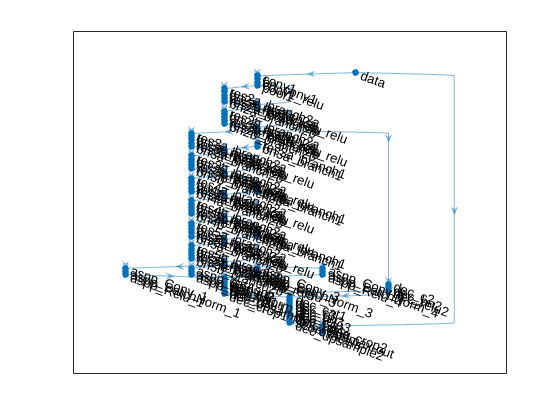

lgraph = replaceLayer(lgraph,"classification",pxLayer);
figure, plot(lgraph)

options of training DeepLab v3+

pximds_valid=pixelLabelImageDatastore(imdsVal, pxdsVal,'OutputSize',[512 640]);
pximds_train=pixelLabelImageDatastore(imdsTrain, pxdsTrain,'OutputSize',[512 640]);
options = trainingOptions('adam', ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 8, ...
    'InitialLearnRate', 0.0005, ...
    'ValidationData', pximds_valid, ...
    'Plots', 'training-progress', ...
    'VerboseFrequency', 10);

training DeepLab v3+

在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：１１　｜　　　２２．９５％　｜　　５３．９０％　｜　　１．４８６２　｜　１．８５７２　｜　　０．０００５　｜
｜　　　１　｜　　　１０　｜　　　　　００：００：１８　｜　　　８８．４２％　｜　　　　　　　　　｜　　０．３１４５　｜　　　　　　　　｜　　０．０００５　｜
｜　　　１　｜　　　２０　｜　　　　　００：００：２６　｜　　　８７．５５％　｜　　　　　　　　　｜　　０．１７３９　｜　　　　　　　　｜　　０．０００５　｜
｜　　　１　｜　　　３０　｜　　　　　００：００：３３　｜　　　９３．８２％　｜　　　　　　　　　｜　　０．１０７８　｜　　　　　　　　｜　　０．０００５　｜
｜　　　１　｜　　　４０　｜　　　　　００：００：４０　｜　　　９１．６２％　｜　　　　　　　　　｜　　０．１２４２　｜　　　　　　　　｜　　０．０００５　｜
｜　　　１　｜　　　５０　｜　　　　　００：００：５３　｜　　　９０．９５％　｜　　９０．７５％　｜　　０．１４０５　｜　０．１４２８　｜　　０．０００５　｜
｜　　　１　｜　　　６０　｜　　　　　００：０１：００　｜　　　９３．６０％　｜　　　　　　　　　｜　　０．１０１０　｜　　　　　　　　｜　　０．０００５　｜
｜　　　１　｜　　　７０　｜　　　　　００：０１：０８　｜　　　８９．６０％　｜　　　　　　　　　｜　　０．１２８７　｜　　　　　　　　｜　　０．０００５　｜
｜　　　１　｜　　　８０　｜

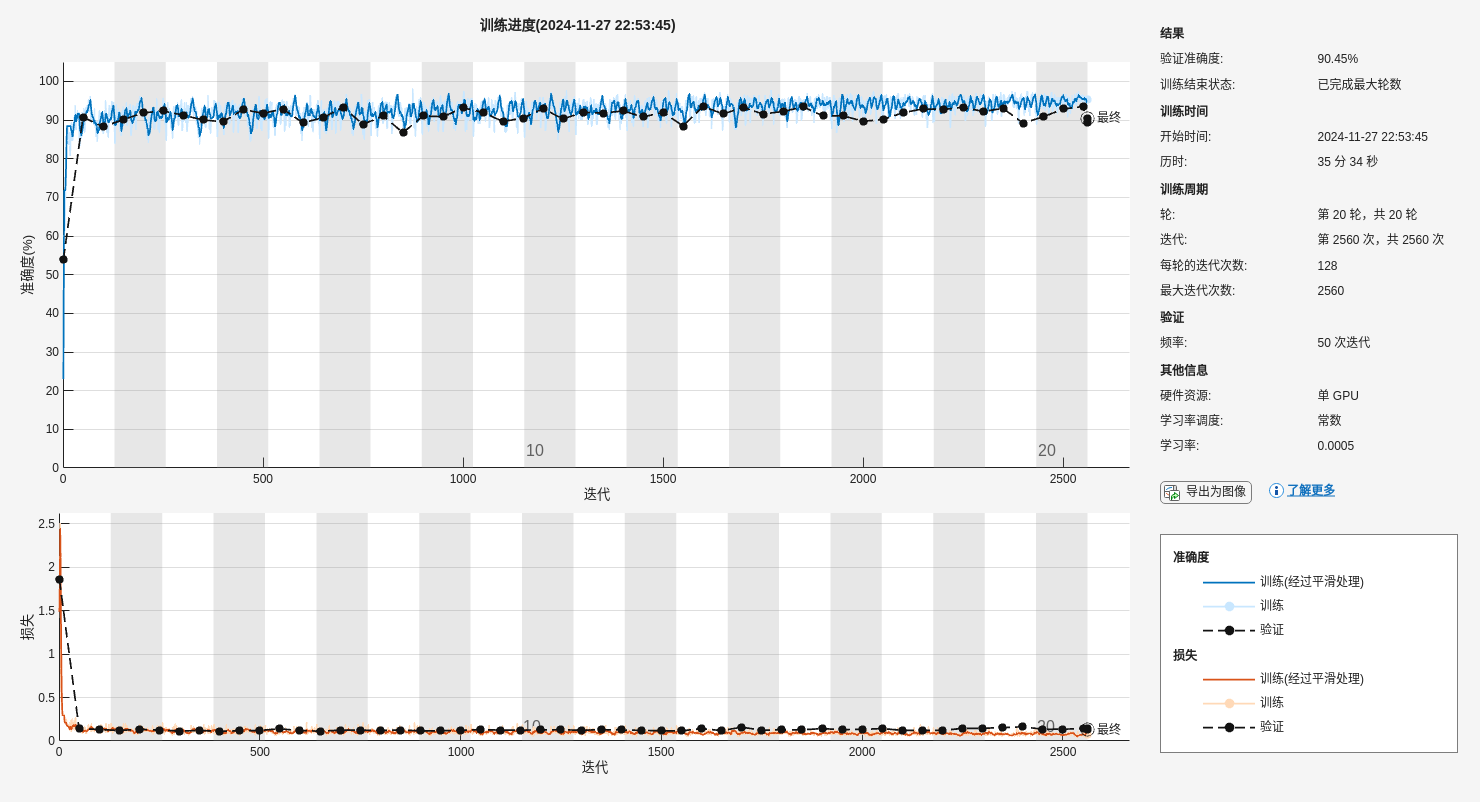

[lgraph, info] = trainNetwork(pximds_train,lgraph,options);

save


% 保存模型
modelFolder = '/home/lzh/hair/trainedModel_unet_segnet_deeplab';
if ~exist(modelFolder, 'dir')
    mkdir(modelFolder);
end
save(fullfile(modelFolder, 'trainedDeeplabv3plus_0005.mat'), 'lgraph');
save('trainedInfo_Deeplabv3plus0005.mat','info');


Supporting Functions

% 数据分割函数
function [imdsTrain, imdsVal, pxdsTrain, pxdsVal] = partitionData(imds, pxds)
    % 获取文件数量
    numFiles = numel(imds.Files);
    shuffledIndices = randperm(numFiles);
    numTrain = round(0.9 * numFiles);
    
    trainingIdx = shuffledIndices(1:numTrain);
    valIdx = shuffledIndices(numTrain+1:end);
    
    imdsTrain = subset(imds, trainingIdx);
    imdsVal = subset(imds, valIdx);
    pxdsTrain = subset(pxds, trainingIdx);
    pxdsVal = subset(pxds, valIdx);
end